## Part 1. Conditional Probability and Bayes’ Formula

## Q1

P_red_transferred = 2/5; % Probability of red being transferred
P_not_red_transferred = 3/5; % Probability of not red being transferred

% Given: P(red | red transferred) = 3/5
% Given: P(red | not red transferred) = 2/5
P_red_given_red_transferred = 3/5;
P_red_given_not_red_transferred = 2/5;

% Calculate P(red) using the law of total probability
P_red = (P_red_given_red_transferred * P_red_transferred) + ...
        (P_red_given_not_red_transferred * P_not_red_transferred);

% Calculate P(red transferred | red) using Bayes' theorem
P_red_transferred_given_red = (P_red_given_red_transferred * P_red_transferred) / P_red;
disp('P(red transferred | red) = P(red | red transferred) * P(red transferred) / P(red)');

P(red transferred | red) = P(red | red transferred) * P(red transferred) / P(red)


display(P_red_transferred_given_red)

P_red_transferred_given_red = 0.5000

## Q2

N_simulations = 10000; 
transferred_balls = NaN(N_simulations, 1); % 10000 rows x 1 column
sampled_balls = NaN(N_simulations, 1);

for i = 1:N_simulations
    jar1 = [1, 1, 1, 0, 0];
    jar2 = [1, 1, 0, 0];
    transferred_balls(i) = randsample(jar1, 1); 
    jar2 = [jar2, transferred_balls(i)]; 
    sampled_balls(i) = randsample(jar2, 1);

end
display(sum(sampled_balls)/N_simulations) % exact numbers will vary by simulation

    0.5197



## Q3

prob_green_transferred_given_green_draw = sum(sampled_balls(transferred_balls == 1))/sum(sampled_balls)

prob_green_transferred_given_green_draw = 0.6927

display(prob_green_transferred_given_green_draw)

prob_green_transferred_given_green_draw = 0.6927

p_pre_calculate = 0.6923

## Part 2. Estimating Population Size with Animal Tagging

## Q4

N_population = 10/(2/10)

N_population = 50

display(N_population)

N_population = 50

## Q5

% If we found 1 out of 10 animals tagged in second-capture
display(10/(1/10))

   100



% What can we get from this result?

## Q6

warning('off', 'all');
nTagged = 20; % Number of tagged fish
nUntagged = 80; % Number of untagged fish
nTotal = 100; % Total number of fish
nSample = 15; % Size of the sample
nSuccess = 4; % Desired number of tagged fish caught
P_collecting_4_tagged = (nchoosek(nTagged, nSuccess) * nchoosek(nUntagged, nSample - nSuccess)) / nchoosek(nTotal, nSample);
disp(['(20 choose 4)*(80 choose 11)/(100 choose 15) = ', num2str(P_collecting_4_tagged)]);

(20 choose 4)*(80 choose 11)/(100 choose 15) = 0.20038


## Q7

nSuccess_zero = 0; % Desired number of tagged fish caught
P_collecting_0_tagged = (nchoosek(nTagged, nSuccess_zero) * nchoosek(nUntagged, nSample - nSuccess_zero)) / nchoosek(nTotal, nSample);
disp(['(20 choose 0)*(80 choose 15)/(100 choose 15) = ', num2str(P_collecting_0_tagged)]);

(20 choose 0)*(80 choose 15)/(100 choose 15) = 0.026194


## Q8

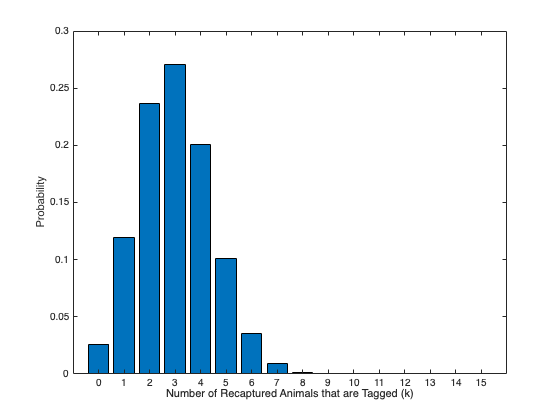

N = 100;
B = 20;
n = 15;
k = 0:15;

probs_k = zeros(16, 1);

for i = 0:15 
    probs_k(i+1) = mark_recapture_prob(N, B, n, k(i+1)); 
end

figure(3) 
bar(k, probs_k) 
xticks(k) 
xlim([-1 n+1]) 
xlabel('Number of Recaptured Animals that are Tagged (k)') 
ylabel('Probability')

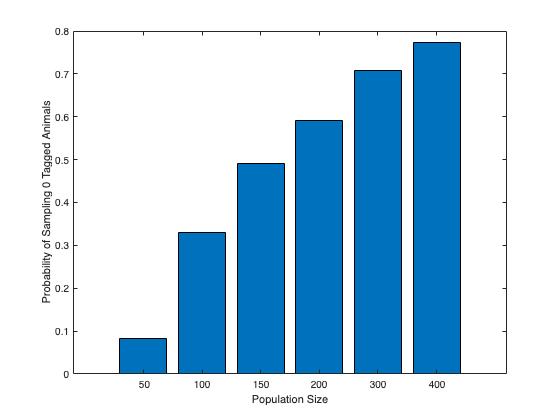

% Example solution and plot:
N = [50, 100, 150, 200, 300, 400]; 
b = [5, 10, 15, 20, 25]; 
p0 = zeros(length(N), length(b)); 
k = 0; 
for i=1:length(N)
    for j=1:length(b)
        p0(i,j) = mark_recapture_prob(N(i), b(j), b(j), k);
    end 
end 
bar(p0(:, 2)) 
xlabel('Population Size') 
xticklabels(cellstr(num2str(N(:)))) 
ylabel('Probability of Sampling 0 Tagged Animals')

## Part 3. Sampling with Replacement

## Q9

% A
N = 20; % Total number of items
B = 5;  % Number of successes in the population
n = 4;  % Number of draws

% Calculate hypergeometric probabilities for k = 0, 1, 2
hypergeometric_probs = [hygepdf(0, N, B, n), hygepdf(1, N, B, n), hygepdf(2, N, B, n)];
Pr_hypergeometric = sum(hypergeometric_probs);

% Calculate binomial probabilities for k = 0, 1, 2
p = B / N; % Success probability in each trial for binomial distribution
binomial_probs = [binopdf(0, n, p), binopdf(1, n, p), binopdf(2, n, p)];
Pr_binomial = sum(binomial_probs);

disp(['Hypergeometric: Pr(k in {0, 1, 2}) = ', num2str(Pr_hypergeometric)]);

Hypergeometric: Pr(k in {0, 1, 2}) = 0.96801


disp(['Binomial: Pr(k in {0, 1, 2}) = ', num2str(Pr_binomial)]);

Binomial: Pr(k in {0, 1, 2}) = 0.94922


% B
N = 1000; % Total number of items
B = 50;  % Number of successes in the population
n = 40;  % Number of draws

% Calculate hypergeometric probabilities for k = 1, 2, 3
hypergeometric_probs = [hygepdf(1, N, B, n), hygepdf(2, N, B, n), hygepdf(3, N, B, n)];
Pr_hypergeometric = sum(hypergeometric_probs);

% Calculate binomial probabilities for k = 1, 2, 3
p = B / N; % Success probability in each trial for binomial distribution
binomial_probs = [binopdf(1, n, p), binopdf(2, n, p), binopdf(3, n, p)];
Pr_binomial = sum(binomial_probs);

disp(['Hypergeometric: Pr(k in {0, 1, 2}) = ', num2str(Pr_hypergeometric)]);

Hypergeometric: Pr(k in {0, 1, 2}) = 0.74257


disp(['Binomial: Pr(k in {0, 1, 2}) = ', num2str(Pr_binomial)]);

Binomial: Pr(k in {0, 1, 2}) = 0.73334
